# Summary Data Analysis 1000 diluted Data

load('NNGP_Real_Data_Copula5000_D1_NEW.mat')
rng(1000)
iters=it;

# MCMC Diagnostics

## Degree of Freedom

MCMC chain of DOF

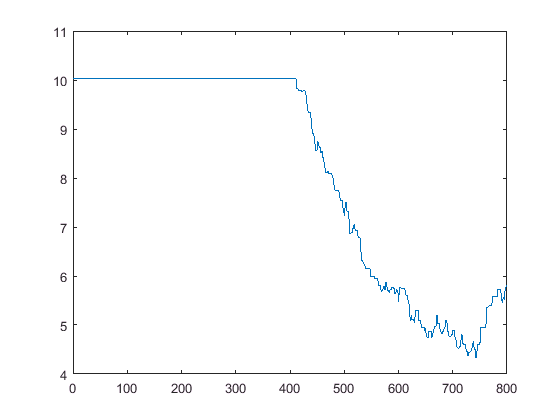

dof_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    dof_curr=obj{1};
   dof_all=[dof_all dof_curr('dof')];
end
plot(dof_all)

Posterior Density of DOF

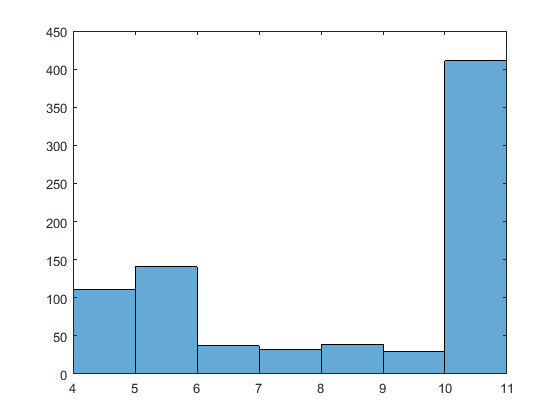

histogram(dof_all)

## Spatial range ($\rho_w$) of Gaussian Process

MCMC of $\rho_w$

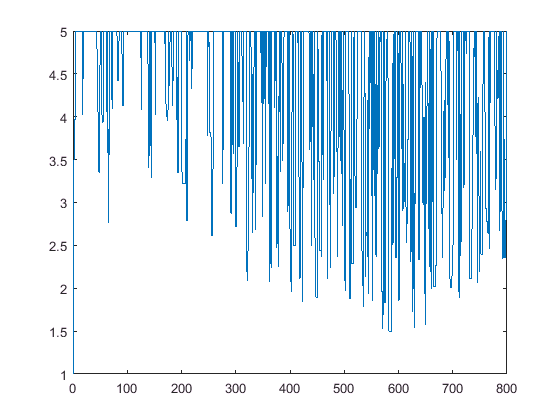

rho_w_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    rho_w_curr=obj{2};
   rho_w_all=[rho_w_all rho_w_curr('rho_w')];
end
plot(rho_w_all)

Posterior Density of $\rho_w$

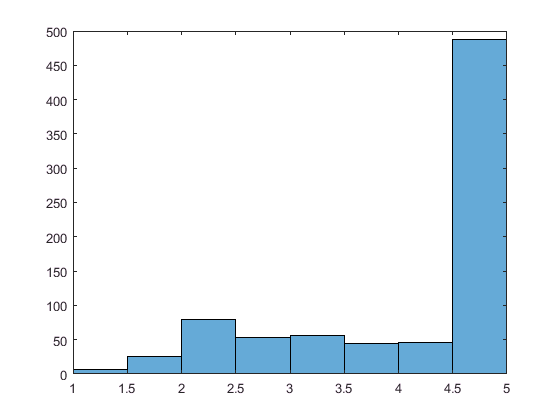

histogram(rho_w_all)

## Spatial range ($\rho_c$) of Gaussian Process

MCMC of $\rho_c$

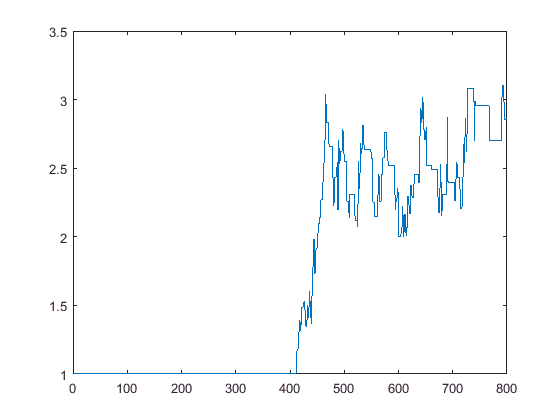

rho_c_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    rho_c_curr=obj{3};
   rho_c_all=[rho_c_all rho_c_curr('rho_c')];
end
plot(rho_c_all)

Posterior Density of $\rho_c$

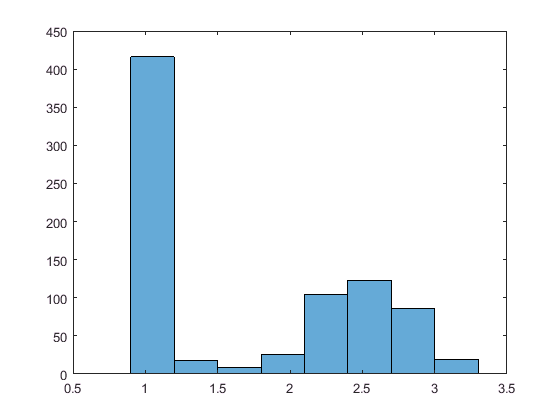

histogram(rho_c_all)

## Spatially Varying Coefficents

MCMC of beta of voxel with signals 

Intercept

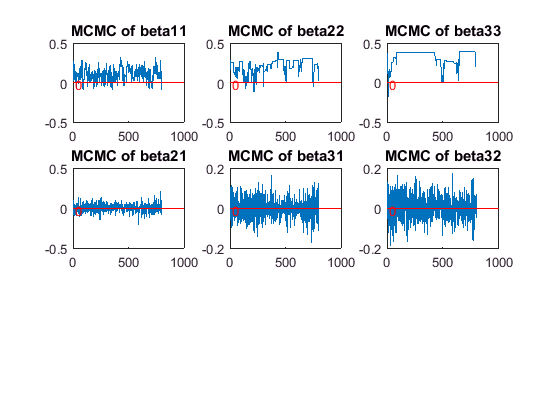

sg=randsample(1:1000,1);

figure
subplot(3,3,1)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta11');
   beta_all=[beta_all my(sg,1)];
end
plot(beta_all)
h =hline(0,'r','0');
title('MCMC of beta11')

subplot(3,3,2)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta22');
   beta_all=[beta_all my(sg,1)];
end
plot(beta_all)
h =hline(0,'r','0');
title('MCMC of beta22')

subplot(3,3,3)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta33');
   beta_all=[beta_all my(sg,1)];
end
plot(beta_all)
h =hline(0,'r','0');
title('MCMC of beta33')

subplot(3,3,4)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta21');
   beta_all=[beta_all my(sg,1)];
end
plot(beta_all)
h =hline(0,'r','0');
title('MCMC of beta21')

subplot(3,3,5)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta31');
   beta_all=[beta_all my(sg,1)];
end
plot(beta_all)
h =hline(0,'r','0');
title('MCMC of beta31')


subplot(3,3,6)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta32');
   beta_all=[beta_all my(sg,1)];
end
plot(beta_all)
h =hline(0,'r','0');
title('MCMC of beta32')

Coefficient

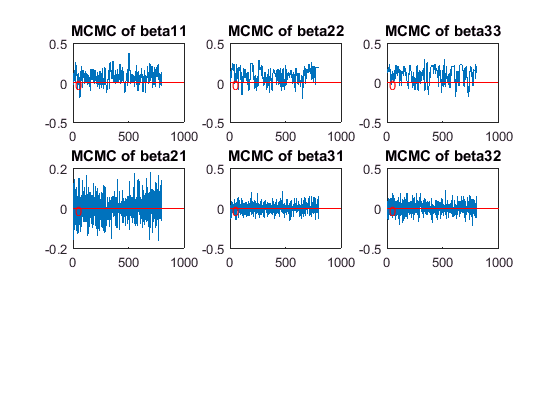

sg=randsample(1:5000,1);

figure
subplot(3,3,1)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta11');
   beta_all=[beta_all my(sg,2)];
end
plot(beta_all)
h =hline(0,'r','0');
title('MCMC of beta11')

subplot(3,3,2)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta22');
   beta_all=[beta_all my(sg,2)];
end
plot(beta_all)
h =hline(0,'r','0');
title('MCMC of beta22')

subplot(3,3,3)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta33');
   beta_all=[beta_all my(sg,2)];
end
plot(beta_all)
h =hline(0,'r','0');
title('MCMC of beta33')

subplot(3,3,4)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta21');
   beta_all=[beta_all my(sg,2)];
end
plot(beta_all)
h =hline(0,'r','0');
title('MCMC of beta21')

subplot(3,3,5)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta31');
   beta_all=[beta_all my(sg,2)];
end
plot(beta_all)
h =hline(0,'r','0');
title('MCMC of beta31')


subplot(3,3,6)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta32');
   beta_all=[beta_all my(sg,2)];
end
plot(beta_all)
h =hline(0,'r','0');
title('MCMC of beta32')